#  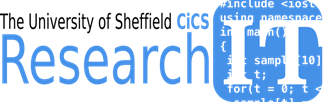                                      

# **GUI and App Building With with Matlab**

## Outline

- Introduction to GUI Building

- Designing the GUI

- Inspecting and Modifying GUI Object Properties

- Component parts of a GUI interface

-   Figure file ( .fig file )

-   Script file (.m file )

- Call-back functions

- Case Study

- App Designer

Here, we cover the technical issues on how to create a GUI interface and present a simple plotting GUI example.

# Introduction to GUI Building

1.Programmatic GUI building

- Hand-code Matlab scripts that generates the figures dialogs etc., setting the properties of graphical objects where necessary

- Everything is saved in a set of .m files ( See example directory: ***surf *** )

2.Creating GUIs via guide

- Start off with a figure into which you can locate various user interface components such as menus, listboxes, radio buttons. This is saved as a figure files ( .fig ) 

- Corresponding to this figure file, Guide also creates a “template” call-backs script ( .m file ) , which can be edited to program the GUI. 

3. App Designer

- App Designer is a design environment for building apps. 

- Provides many of the same controls as GUIDE, the process for building apps is different. 

- Most significantly, the graphics support, generated code, component access, callback coding, and plotting component are different.

**Guide – building user interfaces interactively.**

Guide is an interactive tool for designing and building Graphical User Interfaces (GUI) for your Matlabapplications.  

GUI building process in Matlab using GUIDE involves;

- Designing of the user interface and layout ( The looks!)

- Programming the GUI and its components (The Works!)

- Testing, debugging and finally running it.

## Starting Up GUIDE

- Type ***guide***on the command window.

- This will open the Quickstart GUI template selection window. Matlab provides a few templates to help with the common GUI design task but these are limited in numbers and you will probably need to start with a blank template. 

- The initial layout area is usually resizable by clicking and dragging the handles on the corners of thetemplate area.

[Building GUIs with Matlab](https://uk.mathworks.com/help/matlab/creating_guis/ways-to-build-matlab-guis.html#bu7g5rr)

Using the guide command GUIDE provides options for building a new GUI or opening an exisiting GUI

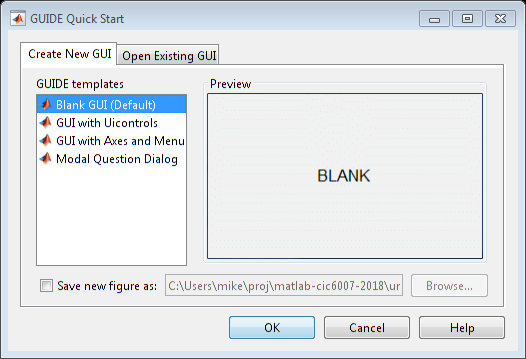

guide

# Designing the GUI

To open an existing GUI use

cd '../matlab_examples/usingmatlab/guiexample/'

guide('guiex2.fig')

cd ..\..\..\presentations\

Hover the moues over the buttons across the top of GUIDE, these are

- Alignment tool 

- menu editor

- Tab order editor

- Toolbar editor

- Editor

- Property Inspector

- Object Browser 

- Run GUI button

[Build a simple App Using GUIDE](https://uk.mathworks.com/help/matlab/creating_guis/about-the-simple-guide-gui-example.html)

[https://uk.mathworks.com/help/matlab/creating_guis/about-the-simple-guide-gui-example.html](https://uk.mathworks.com/help/matlab/creating_guis/about-the-simple-guide-gui-example.html)

- The initial stages of the GUI design will involve selecting the control components we wish to use from the LHS palette  and dragging and dropping them to a location of our choice on the layout area.

- Once dropped into the layout area, these components can be moved around and resized at will until a pleasant interface layout is achieved. 

- It is usually aesthetically pleasing to use correctly proportioned controls, for example all Push-buttons being the same size. This can easily be achieved byright-clicking onto an existing control on the layout panel and selecting <duplicate>to ensure thatmultiple components have the same size and appearance. 

- While a control item is selected; pressing DELor using theEdit-Cut menu will delete that item. Also the Undo button can be used to recover from mistakes.

- As well as getting the proportions of the control elements right, it is also important to get the alignment of the control elements correct and the alignment tool in the toolbar can be used for this purpose.

- All items in the layout panel that needs to be aligned with each other should first be selected as a group. This can be achieved by using the shift + left_clickbutton on each item  in sequence or by choosing the Select tool and clicking and dragging to capture the items in a rectangular area. 

- Now use the alignment tool in the toolbar to align the currently selected items in the lay-out panel.

- When the align objects button is clicked the Align and Distribute Objects panel will be opened on which you will need to select the type of alignment/’smooth distribution’ required ( i.e. vertical, horizontal, equal-spacing ) and press the Apply button to carry out the selected alignment action. 

## Components of a GUI Program

- User interface design and layout

- Customising Component properties

- Callback functions 

# User Interface Design and Layout

- The initial stages of the GUI design will involve selecting the control components we wish to use from the LHS palette  and dragging and dropping them to a location of our choice on the layout area.

- Once dropped into the layout area, these components can be moved around and resized at will until a pleasant interface layout is achieved.

**Designing the interface layout**

The user interface will usually be made up of ;

- Toolbars & Menus

- Input Control components such as ;

-     –Push Buttons, Radio Buttons, Check Boxes ( SWITCHES)

-   –Pop-up Menus, List-Boxes ( SELECTIONS)  

-   –Sliders ( CONTINIOUS CONTROL )

-     –Edit Text ( TEXT method of input ) 

- Graphical Objects 

-     –Axes Objects

- Text Objects

-  –Static Text

- Matlab help pages on GUIDE give a lot of guidance on how to create a good design by making the layout simple and uncluttered.  Refer to those pages for design hints. 

**Components Palette **

Your layout-design task will involve dragging and dropping the GUI control components from the palette onto the layout area. 

- The L.H.S. of the Guide window contains the components palette. 

- *File-> Preferences* option of the GUIDE window will allow you to display the names of the items in the components palette via the Guide: *Preferences > Show Names in the components palette*.

## Grids and Guide-lines

- Normally, the use of the alignment and distribution tool will be sufficient for your layout designs

- Finer controls can be achieved by using the Grids, Rulers and Guide-lines as well as controlling the way objects can be snapped onto grid-lines. 

- Rulers and Guide-lines can be activated via the *Tools->Grids and Rulers*menu item. 

- Once the Rulers are activated, guide-lines can be formed by clicking and dragging the rulers. Guide-lines do not exist in the created GUI. They are only there to make alignments easier by visual means. 

**Panels and Button Groups**

- The items labelled Panels and Button Groups in the components palette are not in themselves control elements but are usually used for grouping together of the control elements. 

- This is desirable when you design the GUI as made up of  plots, graphs etc. that are controlled via various buttons etc located in a single ‘or a few’ control panel(s). 

- A panel can be created in the usual manner by dragging and dropping a panel from the components pallet onto the layout panel.

- Following the creation of a panel, control items that are to be contained by that panel can simply be dragged and dropped onto the panel.  

- A panel that contains control elements can now be moved, sized etc., thus treating all the control elements it contains as a single design item. 

- Panels do not have to contain just the control elements, they can contain anything including axes elements and other panels. Used in this fashion, a GUI can be made to look like a multi component panel containing multiple graphs etc.

**Button Groups**

- Button Groups are like panels but their only real purpose is to group together the Radio Buttons and the Toggle Buttons. 

- These are exclusive-selection items, where only one from a group of control-items will be allowed to be selected during the user interaction.

-  **For example**: User will be asked to select one of the following three options for plot axis type (LINEAR AXIS), ( LOG/LINEAR) , (LOG/LOG) .

-  These options can be presented as three separate radio buttons   ( or toggle switches ) contained within a Button-Group panel.  If they were not contained in a button-group panel, these three controls would operate independently of each other making it possible to select any combinations of them which is not sensible. 

-  Whereas when they are contained in a button-group selection of one would automatically de-select the other two.      

## Toolbar Editor

Note the following features

- Toolbar property editor

- Tool palette

- The bar across the top which is the toolbar layout

# 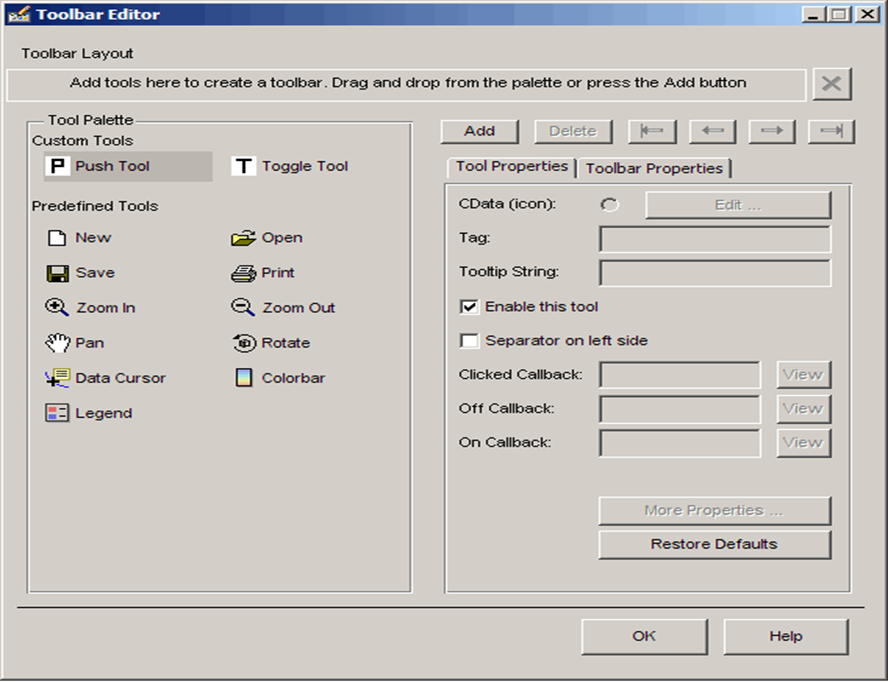

## Menu Editor

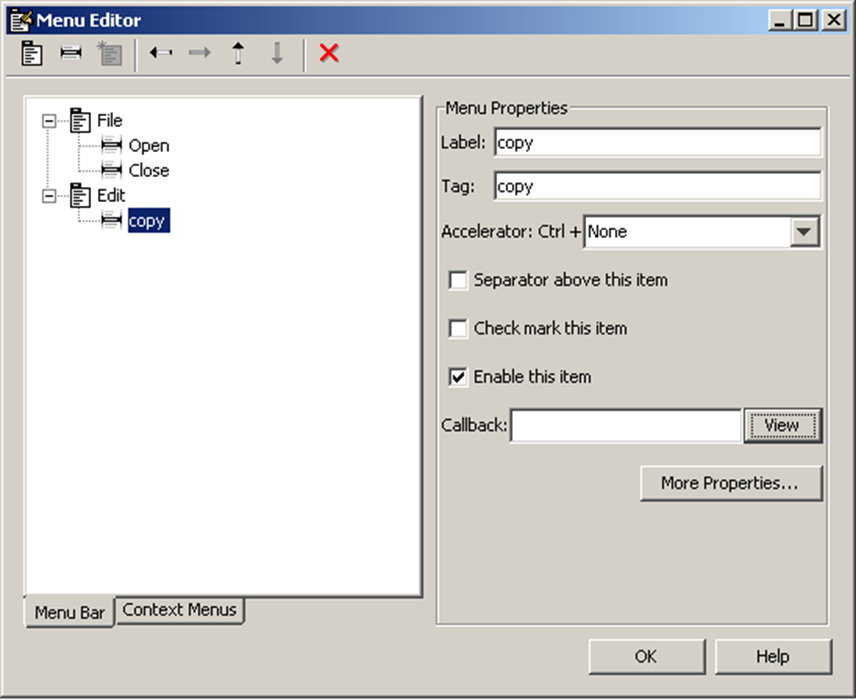

## Context Menus

Context menus can be used to define menus for objects which will pop-up when user right-clicks on it. These menus are defined using the menu-editor and then associated with object(s) by using the property editor and defining the Uicontextmenu Property.

## Saving Your GUI

•Once you are happy with the layout of your GUI, you should save it for future use.

•Save the GUI using the <file> <save> menu or by clicking the save icon. 

•Graphical User Interfaces generated by GUIDE are saved into two closely linked files- namely;

  *your_gui_name*.fig  and *your_gui_name*.m

•The figure (.fig) file contains all the information related to the layout and appearance. 

•The script (.m) file contains all the programming logic aspects of the GUI. 

•Most of the programming components of interest in the .m file will be contained in the set of function-stubs ready for use as call-back functions to various control objects. 

•The task of programming the GUI will be one of finding the suitable code that need to be inserted into these call-back functions.

## The GUI example

For this session we will refer to a graphis based GUI in the folder ` /matlab_examples/usingmatlab/guiexample`

%run from the matlab desktop
%guide('../matlab_examples/usingmatlab/guiexample/guiex2.fig')

The program before editing is as follows

edit('../matlab_examples/usingmatlab/guiexample/guiex2.m')


# Inspecting and Modifying GUI Object Properties

## Property Editor

•Having located the control-elements of your GUI in the layout panel, you can now customise the properties, which includes the appearance of these item.  

•Each element in the layout panel is treated as an object that is contained in the figure which defines the  GUI. 

•Following from that, each object will possess a defined ‘and limited’ set of properties. 

•Some of these properties determine the way that object looks, such as its colour, its title or the fonts used for text output associated with that object.

•There are also properties that determine the action that needs to be performed when a particular interaction is applied to an object, such as mouse-click on a button, slider-dragging with the mouse so on.   

## Properties for GUI Objects

•**String**

  *Text or title to display(e.g. button titles )*

•**Tag**

  *To identify the component during programming*

•**Callback**

  *To specify the action to take when control activated ( .e.g what to do when mouse clicked on button )*

•**Value**

  *Indicates the state of the control*  *object numerically( e.g position of the slider , button on/off)*

## String Properties

•String property of most of the GUI control items determine the titles to be printed on the screen to identify these controls.

•For buttons, check boxes, edit text, and static text, the String text is displayed on or next to the component. These titles will not normally be changed by the user during the execution of the gui.

•For pop-up menus and list-boxes all the items on the menu or the list-box should be entered as a column of n number of strings where; n is the number of options on the menu.

•For an edit text, the String property contains a list of strings that is displayed in the text box. When a user edits the text, the String property is updated. 

## Tags

•Tags are used for identifying the GUI components during programming the interface. Every object created on the GUI panel will have a tag property associated with it. 

•By default, Guide gives simple descriptive values to these TAG properties, such as pushbutton1, slider3 so on and uses these values when it generates the call back functions in the auto-generated .m-file associated with that GUI.  

•For easier understanding and programming of this m-file, we recommend that you define more meaningful tag values for the control components ‘buttons, sliders etc.’ of your GUI such as ‘rescale’, ‘convert’ etc.  

## Using Handles to Access the GUI Properties

•The **handles**structure contains fields that are named with the tagnames of all the components in your gui.  As these structure fields must be unique it is important that all the object ‘tags’  have unique names.

•For example if you have a radio_button which has the ‘tag’ property of ‘mediumwave’  then the handle of that radio_button will be accessible via the field **handles.mediumwave** .

•We can inspect, read and/or set all the properties of the above mentioned radio_button by using the general purpose Matlab **get()**and **set()**functions. 

•For example: 

  **get (handles.mediumwave , ‘Value’ )** will return whether the radio button is currently pressed (1.0) or not (0.0) Note that ‘Value’ is an important property of the radio button that indicates if it is currently in pressed position or not.

•To find out what properties an object has, use the command 

  ***get( handle_to_object )***  which will list all the properties and the current values of that object. However the same can be done much more intuitively and easily by using the property inspector of GUIDE.

## Using Handles to Edit the GUI Properties

•Most of the property related information stored in the handles structure can be altered by using the `get()`and `set() `combination of functions.

•Using the example of the radio button of the previous slide, if we decide to make this button invisible we can do so by setting its property named ‘Visible’ to string ‘off’ by using the **set**function in the following manner:

  ` set (handles.mediumwave , ‘Visible’ , ‘off’ ) `

•When any item stored in the handles structure is changed, ‘*which means almost everything*’ it is important that the handles structure is updated and the effect of these updated values on the GUI itself are implemented.

  This is done by invoking a very useful function named guidata  as follows;

   ` guidata(hObject , handles ) ; `

  We recommend that you routinely add this line to wherever there is a change to any data stored in handles.

•It is also possible to delete objects including the entire GUI window by using the delete command with the object handle. For example if the GUI’s ‘tag’ is ‘figure1’ then 

      `delete( handles.figure1 )` 

will close the GUI. A useful feature for programming the ‘quit’ action.

The program before editing is as follows

## The guiexample

For the code section below we introduce the callback_readme function to handle reading of input data using a read file dialog such as the uigetfile function. The particular program uses the global variable to refer to three data structures temp, pres and volt

edit('../matlab_examples/usingmatlab/guiexample/guiex2c.m')

# Writing Code for the User Interface

•After laying out the GUI and setting its component properties, the next step will be to program its behaviour. 

•The code contained in the callback functions will control how the GUI responds to events such as button clicks, menu item selection, window resizing as well as creation and deletion of components. 

•There will normally ‘but not always’ be one callback function per component on the GUI interface plus a couple of extra callback functions relating to the initialisation and output onto Matlab window. All these functions will be contained in a single .m file generated by GUIDE when you save your gui. (*your_gui.m*)

## Callback Functions

•This is the most important property of the control objects.

•Callback property determines what action needs to be taken when the user activates that object ( for example by clicking on the object, selecting an item from the list-box or choosing a menu item etc. ) Most, if not all, the programming related to your GUI will be contained in the callback functions.

•Callback property will normally be set to the name of a function ‘as a string variable’ that needs to be invoked, but it can also contain a Matlab expression enclosed in a string ( for simple tasks ) .

## Callback Function Names

•Names of the callback functions for each gui component will also be automatically generated by GUIDE using the convention;

•   *function <objects_tag>_<event_to_handle>*

•For example; the function that handles the listbox selection events for a listbox with tag <listbox2> will be named 

•  *function listbox2_Callback*

•A function that handles a key-press over a button with tag ‘redbox1’ will be named  *function redbox1_KeyPressFcn*

•There will also be the following automatically generated callback functions namely;

•*<guiname>_OpeningFcn* : For use in initialisation just before the gui is made visible.*<guiname>_OutputFCn*: For use to output messages onto the Matlabs command output window

## Coding the Callback Functions

•Programming the behaviour of your gui will involve inserting your own Matlab code into the call back functions in the gui’s .m file.  

•Initially GUIDE would have generated all the commonly needed callback functions but they will only be simple stubs, i.e. functions that contain very little or no executable code. Never-the-less this code is ready and functioning from the very start that can be run to confirm that all the mouse-clicks, slider-bars, pop-up menus etc. operate as expected. 

•Without your own code not yet being in place, all your interactions will be generating calls to the corresponding callback functions that simply return control without doing any real work.   

## GUI .m file and the Callback Functions

•The .m file generated by GUIDE is made up of a list of callback functions. 

•There is one main function that has the same name as your GUI and the rest of them are coded as the subfunctions of this main function.

•The main function is executed as your GUI is loaded. However the subfunctions are only executed if the user interactions invoke them via the callback properties of the objects. 

•The main feature of subfunctions is the fact that they can only be invoked by the containing main function. This ensures that a call_back function designed for your GUI is not by accident called from somewhere else.  This is why GUIDE uses subfunctions.

## The guiexample

For the code section below we introduce the listbox1_Callback function to alter the axes labels

 three data structures temp, pres and volt

  In particular note the following

- Using the handles structure to pick out properties` axes( handles.axes1 );`

- Setting a specific data field using the set functions and the handles structure e.g. `set( handles.graphlabel ,'String' , plot_title );`

- The call to update the handles structure` guidata(hObject, handles);`

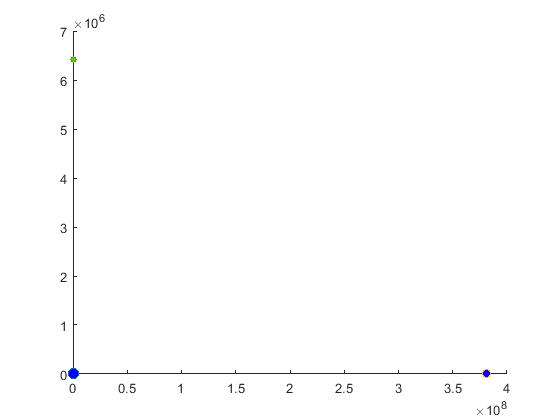

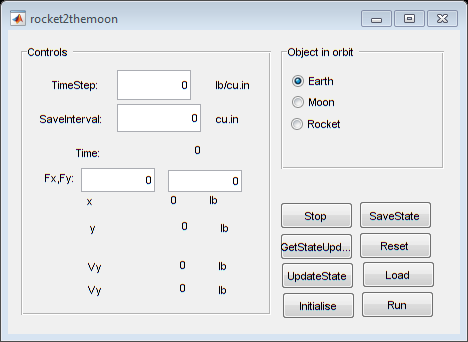

%  

%   axes( handles.axes1 );
%    cla;
%    data_index = get( hObject , 'Value' );
%    switch data_index
%        case 1
%            plot_data = handles.temp ;
%            plot_title = 'TEMPERATURE VARIATION ';
%        case 2 
%            plot_data = handles.pres;
%            plot_title = 'PRESSURE VARIATION ' ;        
%        case 3 
%            plot_data = handles.volt;
%            plot_title = 'VOLTAGE VARIATION ' ;         
%    end
%    plot(plot_data) ;
%    set( handles.graphlabel ,'String' , plot_title );
%  % Update handles structure
%    guidata(hObject, handles);


edit('../matlab_examples/usingmatlab/guiexample/guiex2d.m')

## Data Transfer between Callback Functions

•Although all the callback functions are contained within the same .m file, they are semantically separate pieces of code that do not share any data except the data passed to them via the input parameters.

•To make the task of passing data easier, GUIDE inserts code for the creation of a handles structure that contains all the data for the GUI objects such as the control buttons, menus, axes.

•The handles structure (named: handles) is passed as an input parameter to all the callback functions that make up the GUI.

•Access to data is achieved by accessing the components of this handlesstructure using the rules relating to structures. See Matlab part II lecture notes.

## Adding Program Data to the Handles

•Although there are other ways of accessing data that is to be used/created within your gui, the recommended method remains to be via the handles structure. 

•This is done very easily by simply defining new field in the ‘handles’ structure. 

•For example, the following code section within any one of the call-back functions will create a new field named *mydata*and update the data structures to reflect this change.

    `A = rand(10,10);`

`  handles.mydata = A ;`

`  guidata(hObject , handles ) ; `

•Having stored the matrix A into the handles structure it can now be retrieved from within another callback function by simply;

   ` A = handles.mydata ;`

•Another method of sharing data between the call_back functions can be by the use of the`persistent` and `global` declarations which will make data declared in this way available without having to store and retrieve to/from the handles structure. This is not a recommended method by MathWorks. 

## The guiexample

For the code section below we introduce the smooth_Callback which executes on the user pressing the smooth button

 three data structures temp, pres and volt

  In particular note the following

- Using the handles structure to pick out properties` axes( handles.smoothfactor ); `

- note the smoothfactor control visibility is toggled on and off using the command  `set (handles.smoothfactor , 'visible',  'off' ) ;`

- Setting a specific data field using the set functions and the handles structure e.g. `set( handles.graphlabel ,'String' , plot_title );`

- The call to update the handles structure` guidata(hObject, handles);`

`Updating smooth_callback`

% % Hint: get(hObject,'Value') returns toggle state of smooth
%   if get ( handles.smooth , 'Value' ) == get (handles.smooth,'Min') 
% % smooth is OFF .
%       set (handles.smoothfactor , 'visible',  'off' ) ;
% 
%   else
%       set (handles.smoothfactor , 'visible',  'on' ) ; 
%       sm_min = get (handles.smoothfactor , 'Min' );
%       set( handles.smoothfactor , 'Value' , sm_min ); 
%   end
%       plot_data = handles.plot_data;
%       plot(plot_data) ;

the smoothfactor_callback function responds to the user editing the smoothing factor and edits the plot accordingly

%       plot_data = handles.plot_data ;
%       clear cga;
%       s_window= get ( handles.smoothfactor ,'Value' );
%       s_window = round(s_window) ;
%       filt = ones(1,s_window) / s_window ;
%       plot_data = filter( filt ,1 , plot_data );
%       plot(plot_data ) ;



edit('../matlab_examples/usingmatlab/guiexample/guiex2e.m')

## Additional GUI Components and Dialogs

• `msgbox`   : Display a message in a window

• `errordlg`  : Display error messages in a fresh window

• `uigetfile`: Help select file(s) via a file-open window

• `uiputfile`: Read name of a file that will be used for saving information (via **print**or **saveas**for figures, via **save**for data ) 

`• uitable` : Display data as a table

 The final example guiex2f shows examples radio buttons, bittons in panels and the dialog panel

The pushbutton1_callback responds to the popup selection dialog

% axes(handles.axes1);
% cla;
% 
% popup_sel_index = get(handles.popupmenu1, 'Value');
% switch popup_sel_index
%     case 1
%         plot(rand(5));
%     case 2
%         plot(sin(1:0.01:25.99));
%     case 3
%         bar(1:.5:10);
%     case 4
%         plot(membrane);
%     case 5
%         surf(peaks);
% end

edit('../matlab_examples/usingmatlab/guiexample/guiex2f.m')

# Case Study

For the mission-moon case study we started from a script based application and developed this into a function based program complete with unit tests and data structures. 

edit('../matlab_examples/casestudies/mission-moon/code-006-gui/startrocket2moon.m')

Using the above script: 

- Provided instructions for calling the functions,

- enabled us to provide a method for stop/starting the simulation

- modifying the state 

- saving and reloading the state of the system

Program usability is enhanced  by improving user interaction through the provision of a graphical user interface a simple example for the mission moon case study is shown below

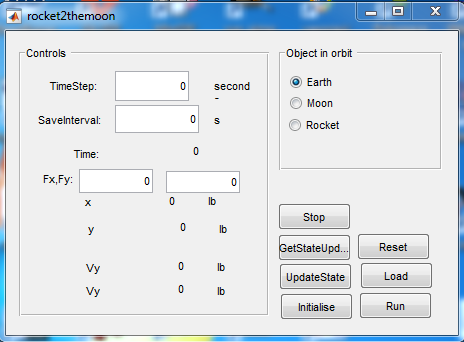

Through the provision of selection boxes, edit boxes and an array of buttons we are able to capture the requirements identified above. The design process is as identifed in the slides.

- Placing the desired GUI components on the initial canvas

- Editing handles and callbacks to provide the correct behaviour

- Addition of a function routine to execute the simulation and run through each step

Features of the program which should be noted

- Use of the `state`, `control`, `const` and `figh` data structures to contain the data required to run the simulation, these have been made accesible via handles in the` initialize_gui` function.

- The graphical display is initialized as a separate figure window in the `initialize_gui` function by calling our  `startrocketgraphics` function

- Unusually we utlize a global variable` stop_state` to control the execution of simulation steps

It is recommended that the following `rocket2themoon` script is run from the matlab command window

cd '../matlab_examples/casestudies/mission-moon/code-006-gui/'
%rocket2themoon


cd '../../../../presentations'

Clearly many enhancements can be made to this GUI program the point is that we have seen this application evolve from a sequence of prototyping scripts to a function based program with data structures, unit tests and a graphical user interface.

Simple modifications which are a good exercise are as follows

- Correct the presented units for the x,y, vx,vy static text boxes

- Add menu or toolbar items to allow the user to call the distancedlg and orbitalspeeddlg which are customised dialogs developed using GUDE

# Matlab App Builder

Matlab is advancing towards web-based GUI. The basic underlying  technology is more-or-less stable: an HTML/Javascript webpage that is  created-on-the-fly and rendered in a stripped-down browser window (based on Chromium-based [jxBrowser](https://www.teamdev.com/jxbrowser) in recent years). However, the exact mechanism by which the controls  (“widgets”) are actually converted into visible components (currently  based on the [Dojo toolkit](https://dojotoolkit.org) and its Dijit UI library) and interact with Matlab (i.e., the internal  Matlab class structures that interact with the browser and Dojo) is  still undergoing changes and is not quite as stable.

Web-based GUI is often referred to as “App-Designed” (AD) GUI, because  using the Matlab App Designer is the typical way to create and customize such GUIs. However, just as great-looking GUIs could be created  programmatically rather than with GUIDE, so too can web-based GUIS be  created programmatically, using regular built-in Matlab commands such as ***uifigure***, ***uibutton*** and ***uitable***. It has been suggested that the new GUIs should  be referred to as “uifigures” or “web GUIs”, and not as “AD GUIs”.

[App Designer](https://uk.mathworks.com/help/matlab/creating_guis/create-and-run-a-simple-app-using-app-designer.html)

[Differences between App Designer and GUIDE](https://uk.mathworks.com/help/matlab/creating_guis/differences-between-app-designer-and-guide.html)